# Load and display robot

clear
clc
close all
addpath("Funtions\")

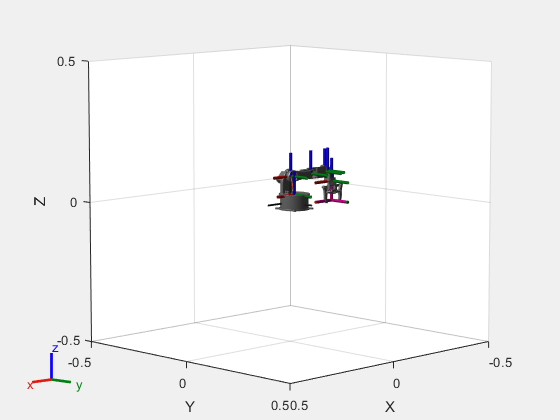

robot = importrobot("Robot_MlabFC_description\urdf\Robot_MlabFC.xacro");

gravityVec = [0 0 -9.80665];
robot.Gravity = gravityVec;

% Add another massless coordinate frame for the end effector
eeOffset = -0.07;
eeBody = robotics.RigidBody('end_effector');
eeBody.Mass = 0;
eeBody.Inertia = [0 0 0 0 0 0];
setFixedTransform(eeBody.Joint,trvec2tform([0 0 eeOffset]));
addBody(robot,eeBody,'component6_1')

%axes.CameraPositionMode = 'auto';
axes = show(robot);

showdetails(robot)

--------------------
Robot: (7 bodies)

 Idx           Body Name              Joint Name              Joint Type           Parent Name(Idx)   Children Name(s)
 ---           ---------              ----------              ----------           ----------------   ----------------
   1        component1_1              Revolute 1                revolute               base_link(0)   component2_1(2)  
   2        component2_1              Revolute 2                revolute            component1_1(1)   component3_1(3)  
   3        component3_1              Revolute 3                revolute            component2_1(2)   component4_1(4)  
   4        component4_1              Revolute 4                revolute            component3_1(3)   component5_1(5)  
   5        component5_1              Revolute 5                revolute            component4_1(4)   component6_1(6)  
   6        component6_1              Revolute 6                revolute            component5_1(5)   end_effector(7)  
  

## Show

close all;

config = homeConfiguration(robot);
show(robot,config);

% figure
% config(1).JointPosition = deg2rad(0);
% show(robot,config);
% figure
% config(1).JointPosition = deg2rad(90);
% show(robot,config);
% figure
% config(5).JointPosition = deg2rad(90);
% show(robot,config);

## Create a set of desired waypoints

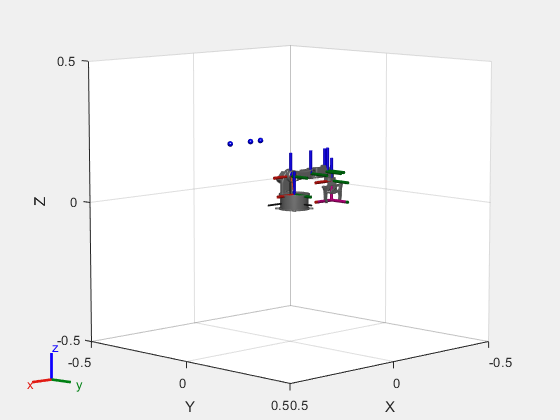

clear wayPoints WaypointVels

waypointType = 'simple'; % or 'complex'
switch waypointType
    case 'simple'
        wayPoints = [-0.05 -0.2 0.2; 0.0 -0.2 0.2; 0.1 -0.2 0.2]; % Alternate set of wayPoints
        wayPointVels = [0.01 0 0;-0.01 0 0; -0.01 0 0];
    case 'complex'
        wayPoints = [0.02 -0.02 0.02;0.015 0 0.28;0.015 0.05 0.02; 0.015 0.09 0.015;0.01 0.012 0.01; 0.04 0.01 0.02;0.025 0 0.015; 0.02 0.02 0.02];
        wayPointVels = [0 0 0; 0 0.05 0; 0 0.025 -0.025; 0 0.025 -0.025;-0.1 0 0;0.05 0 0;0 -0.1 0;0 0 0];
end
exampleHelperPlotWaypoints(wayPoints);

## Create a set of desired waypoints 2

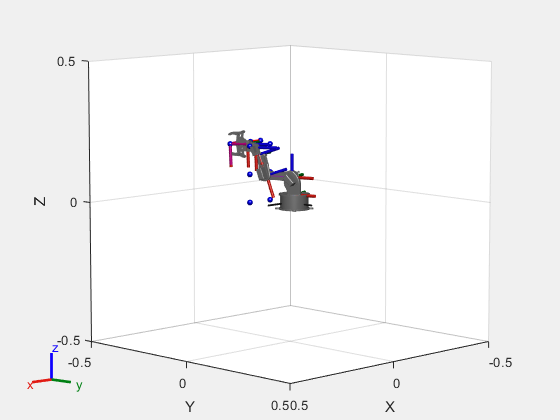


clear wayPoints WaypointVels

waypointType = 'simple';
switch waypointType
    case 'simple'
        wayPoints = [ 0 -0.1 0;
                      0.1 -0.1 0;
                      0.1 -0.1 0.1;
                      0.1 -0.1 0.2;
                      0 -0.1 0.2;
                      0 -0.1 0.1;
                      0 -0.1 0
                     ];
        wayPointVels = [0 0.05 0; 
                        0 0.025 0 
                       0 0.025 0;
                       0 0.025 0;
                       0 0.025 0;
                       0 0.025 0;
                       0 0.025 0;
                       0 0.05 0]; 
end
exampleHelperPlotWaypoints(wayPoints);

## Create a smooth trajectory from the waypoints

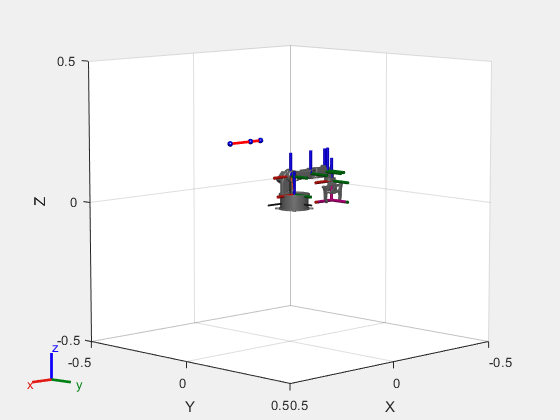

clear trajectory wpTimes trajTimes

numTotalPoints = size(wayPoints,1)*10;
waypointTime = 4;
trajType = 'trapezoidal'; % or 'trapezoidal'
switch trajType
    case 'trapezoidal'
        trajectory = trapveltraj(wayPoints',numTotalPoints,'EndTime',waypointTime);
    case 'cubic'
        wpTimes = (0:size(wayPoints,1)-1)*waypointTime;
        trajTimes = linspace(0,wpTimes(end),numTotalPoints);
        trajectory = cubicpolytraj(wayPoints',wpTimes,trajTimes, ...
                     'VelocityBoundaryCondition',wayPointVels');
end
% Plot trajectory spline and waypoints
hold on
plot3(trajectory(1,:),trajectory(2,:),trajectory(3,:),'r-','LineWidth',2);

## Perform Inverse Kinematics

% Use desired weights for solution (First three are orientation, last three are translation)
clear ik configSoln solnInfo 

ik = robotics.InverseKinematics('RigidBodyTree',robot);
weights = [0 0 0 1 1 1];
initialguess = robot.homeConfiguration;

% Call inverse kinematics solver for every end-effector position using the
% previous configuration as initial guess
for idx = 1:size(trajectory,2)
    tform = trvec2tform(trajectory(:,idx)');
    
    % with x pointing downward for end effector pose
    tform(1,1)=0;
    tform(1,3)=1;
    tform(3,1)=-1;
    tform(3,3)=0;
    %

    [configSoln(idx,:),solIngo] = ik('end_effector',tform,weights,initialguess);
    initialguess = configSoln(idx,:);
end


## Visualize robot configurations

title('Robot waypoint tracking visualization')
axis([-0.5 0.7 -0.7 0.7 -0.5 1.0]);

% Cycle to visualize the robot
for idx = 1:size(trajectory,2)
    show(robot, configSoln(idx,:), 'PreservePlot', false);
    pause(0.3) % Pause to visualize each step
end
hold off

## Establish the connection to the Microcontroller

% (set the COM port as required).
mc = "Esp"; % "Esp" "Arduino"
switch mc
    case "Arduino"
        puerto = 'COM3'; % Change this according to the port you are using
        baudRate = 9600; % Baud rate

    case "Esp"
        puerto = 'COM4'; 
        baudRate = 115200;
end
Mcontrol = serialport(puerto, baudRate);

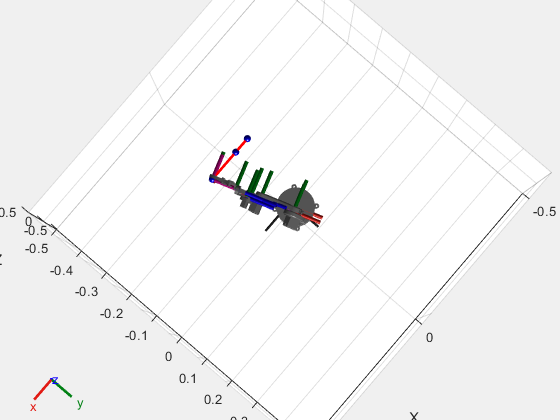

% Initialize the vectors for storing the angles
numServos = 6; % Number of servos (adjust if you have more or less servos)
anglesRad = zeros(size(configSoln, 1), numServos); % Angles in radians
anglesDeg = zeros(size(configSoln, 1), numServos); % Angles in degrees

% Calculate and store all angles before sending the data
for idx = 1:size(configSoln, 1)
    for jointIdx = 1:numServos
        jointPosition = configSoln(idx, jointIdx).JointPosition; % Extraer la posición articular en radianes
        
        % Special setting for the third axis
        if jointIdx == 3
            jointPosition = jointPosition *(-1) + (pi/2); % Ajuste específico para el rango [0, π]
        end
        
        % Convert to degrees
        angleDeg = rad2deg(jointPosition);
        
        % Store calculated values
        anglesRad(idx, jointIdx) = jointPosition; 
        anglesDeg(idx, jointIdx) = angleDeg; 
    end
end

% Send the angle rows to the microcontroller sequentially
for idx = 1:size(configSoln, 1)
    show(robot, configSoln(idx,:), 'PreservePlot', false); % Mostrar en simulación
    
    %  Create a string of angles to send
    anglesString = sprintf('%d,%d,%d,%d,%d,%d', anglesDeg(idx, 1:numServos));
    
    % Send the angles to the Microcontroller
    writeline(Mcontrol, anglesString);
    
    % General pause between each complete configuration
    pause(0.5); % Adjust this as needed
end


% Send command to move to “home” position
pause(2);
writeline(Mcontrol, 'home');
pause(0.5);

% Clear serial connection object
clear Mcontrol;

## Print final angles

disp('Ángulos de todos los servos durante la operación:');

Ángulos de todos los servos durante la operación:


for idx = 1:size(anglesRad, 1)
    fprintf('Paso %d:\n', idx);
    fprintf('   Ángulos en radianes: %s\n', mat2str(anglesRad(idx, :)));
    fprintf('   Ángulos en grados: %s\n', mat2str(anglesDeg(idx, :)));
end

Paso 1:


   Ángulos en radianes: [1.23363238785297 0 0.169839649342304 0 0.0920295648266922 0]


   Ángulos en grados: [70.6819292946212 0 9.73109510129587 0 5.27290565499507 0]


Paso 2:


   Ángulos en radianes: [1.23587371558325 0 0.168701323082161 0 0.0906997800068549 0]


   Ángulos en grados: [70.8103479140717 0 9.66587381088079 0 5.19671459715783 0]


Paso 3:


   Ángulos en radianes: [1.24261513129352 0 0.165358181308976 0 0.0868015982866453 0]


   Ángulos en grados: [71.1966025822132 0 9.47432589696338 0 4.97336523681477 0]


Paso 4:


   Ángulos en radianes: [1.25390783057292 0 0.160026167100368 0 0.080606748916502 0]


   Ángulos en grados: [71.8436265902332 0 9.16882398650633 0 4.61842651318628 0]


Paso 5:


   Ángulos en radianes: [1.26983331280679 0 0.15306669226593 0 0.0725625504085986 0]


   Ángulos en grados: [72.7560895089449 0 8.77007545086554 0 4.15752788911799 0]


Paso 6:


   Ángulos en radianes: [1.29043314015182 0 0.14501236636751 0 0.0633115325209709 0]


   Ángulos en grados: [73.9363726745131 0 8.30859657006319 0 3.62748360795689 0]


Paso 7:


   Ángulos en radianes: [1.31284673730479 0 0.137429296899577 0 0.054659391842635 0]


   Ángulos en grados: [75.2205771950847 0 7.8741186937961 0 3.13175246333479 0]


Paso 8:


   Ángulos en radianes: [1.33546813636804 0 0.130988207016211 0 0.0473541529534606 0]


   Ángulos en grados: [76.5166878880904 0 7.50507142801479 0 2.71319310665025 0]


Paso 9:


   Ángulos en radianes: [1.35827598876857 0 0.125695280891275 0 0.0413813438970586 0]


   Ángulos en grados: [77.8234815703978 0 7.20180909978147 0 2.37097635588091 0]


Paso 10:


   Ángulos en radianes: [1.38124789220493 0 0.121555933954063 0 0.0367293060280674 0]


   Ángulos en grados: [79.1396746846835 0 6.96464199033881 0 2.10443421985267 0]


Paso 11:


   Ángulos en radianes: [1.40409414191573 0 0.118602286646243 0 0.0334200344444167 0]


   Ángulos en grados: [80.4486683708142 0 6.79541046543054 0 1.91482692484692 0]


Paso 12:


   Ángulos en radianes: [1.42331004891018 0 0.117002072471642 0 0.0316307027112019 0]


   Ángulos en grados: [81.5496587411122 0 6.70372494690887 0 1.81230576838488 0]


Paso 13:


   Ángulos en radianes: [1.43776609219784 0 0.116324665523924 0 0.0308739904054456 0]


   Ángulos en grados: [82.3779290099535 0 6.66491238779179 0 1.76894934695943 0]


Paso 14:


   Ángulos en radianes: [1.44742112946942 0 0.116122175940523 0 0.0306478818950914 0]


   Ángulos en grados: [82.9311218966567 0 6.65331058926758 0 1.75599428360415 0]


Paso 15:


   Ángulos en radianes: [1.4522532827862 0 0.116095690593201 0 0.0306183163934431 0]


   Ángulos en grados: [83.2079838876681 0 6.65179309064708 0 1.75430030514051 0]


Paso 16:


   Ángulos en radianes: [1.45406606473146 0 0.116098600621862 0 0.0306215607283015 0]


   Ángulos en grados: [83.3118486423092 0 6.65195982300759 0 1.75448619183522 0]


Paso 17:


   Ángulos en radianes: [1.4637403820474 0 0.116232505333585 0 0.0307710754191034 0]


   Ángulos en grados: [83.8661461941828 0 6.65963199784624 0 1.76305275259338 0]


Paso 18:


   Ángulos en radianes: [1.48311417630813 0 0.117098220580601 0 0.0317381433256979 0]


   Ángulos en grados: [84.9761828384771 0 6.7092338277604 0 1.81846166214379 0]


Paso 19:


   Ángulos en radianes: [1.51221040865205 0 0.119889981263321 0 0.0348617238717181 0]


   Ángulos en grados: [86.6432741515158 0 6.86918993229081 0 1.99742964439992 0]


Paso 20:


   Ángulos en radianes: [1.55099504688878 0 0.126391309796071 0 0.0421652203464664 0]


   Ángulos en grados: [88.8654702324225 0 7.24168861844539 0 2.41588916809167 0]


Paso 21:


   Ángulos en radianes: [1.59715683653736 0 0.13829339971812 0 0.0556424947684701 0]


   Ángulos en grados: [91.5103459540568 0 7.92362813836395 0 3.1880801118121 0]


Paso 22:


   Ángulos en radianes: [1.64348837913135 0 0.15487171409028 0 0.0746443958005257 0]


   Ángulos en grados: [94.1649478030227 0 8.8734955833298 0 4.27680884367417 0]


Paso 23:


   Ángulos en radianes: [1.68926383603711 0 0.175960182652465 0 0.0992010258400685 0]


   Ángulos en grados: [96.7876882890057 0 10.0817758283373 0 5.68380010400415 0]


Paso 24:


   Ángulos en radianes: [1.73431051217051 0 0.201507670288978 0 0.129525889745713 0]


   Ángulos en grados: [99.3686727125426 0 11.5455390470722 0 7.42128682010617 0]


Paso 25:


   Ángulos en radianes: [1.77847393300396 0 0.23147972007687 0 0.165903428434579 0]


   Ángulos en grados: [101.899050335159 0 13.2628110032743 0 9.50556625605207 0]


Paso 26:


   Ángulos en radianes: [1.81855692030511 0 0.263257084194384 0 0.205410953181492 0]


   Ángulos en grados: [104.195636337792 0 15.0835198512584 0 11.7691806830589 0]


Paso 27:


   Ángulos en radianes: [1.84916150089565 0 0.290722399925072 0 0.240331047551064 0]


   Ángulos en grados: [105.949149639398 0 16.6571665256211 0 13.7699547106338 0]


Paso 28:


   Ángulos en radianes: [1.87064104517536 0 0.311801631776774 0 0.267615222724556 0]


   Ángulos en grados: [107.17983687249 0 17.8649175461013 0 15.3332227955706 0]


Paso 29:


   Ángulos en radianes: [1.88337085166717 0 0.325045768396158 0 0.284971673794039 0]


   Ángulos en grados: [107.909201058488 0 18.6237506776867 0 16.3276741891773 0]


Paso 30:


   Ángulos en radianes: [1.88758730212258 0 0.32956150132371 0 0.290927131942006 0]


   Ángulos en grados: [108.150785874109 0 18.8824831158437 0 16.6688968061226 0]
